clear all
close all

[data,Fs]=audioread('Audio/KDE_Startup.wav');

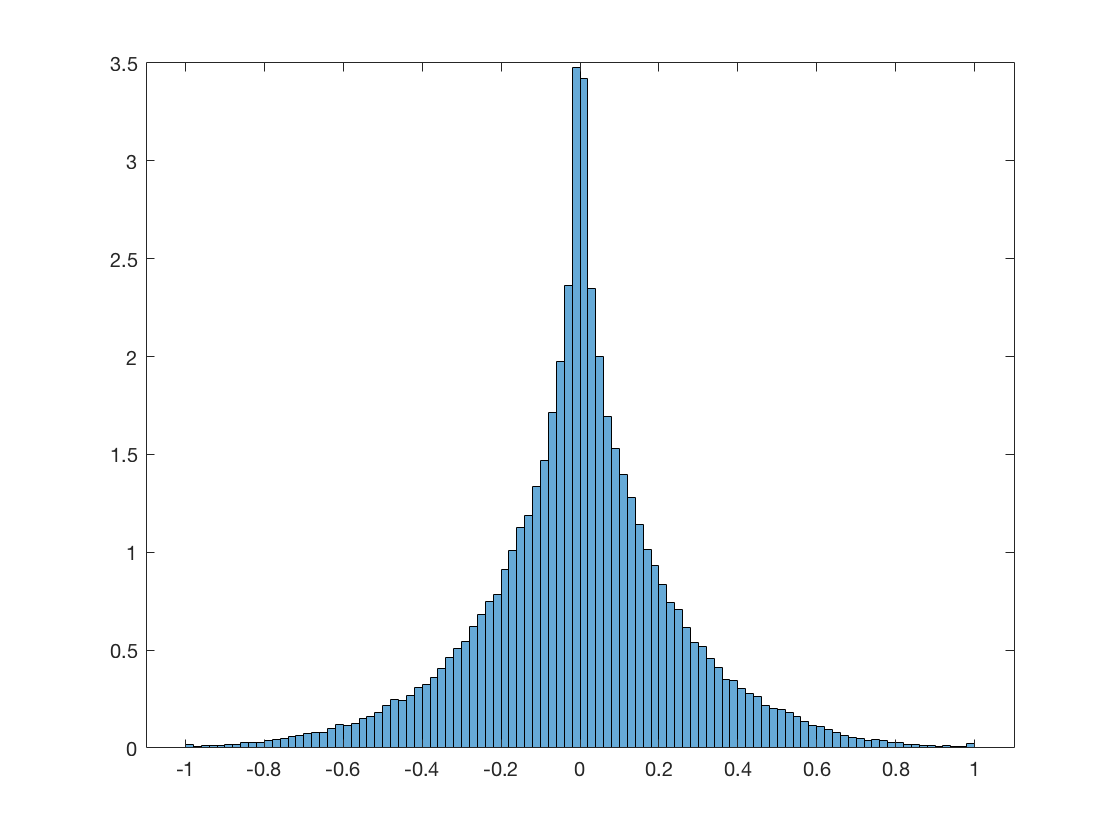

data=data(:,1)';

V = max(abs(data));
nbit=6;
M=2^nbit;
DeltaV=2*V/M;
pe=1e-5;
Tc = 1/Fs;
B = 1/(2*Tc);

data_ = data*(1/V);

figure(1);
histogram(data_, 100, 'Normalization', 'pdf')

Quantizzazione

partition=[-V+DeltaV:DeltaV:V-DeltaV];
codebook=[-V+DeltaV/2:DeltaV:V-DeltaV/2];
[index,quants]=quantiz(data_,partition,codebook);

Decimale to Binario

word=de2bi(index,nbit);

Disturbo gaussiano sul canale

word_out=bsc(word,pe);

Ricevitore

index_out=bi2de(word_out);
sig_out=codebook(index_out+1);
err=sig_out-data_;

Spettro del segnale ricevuto

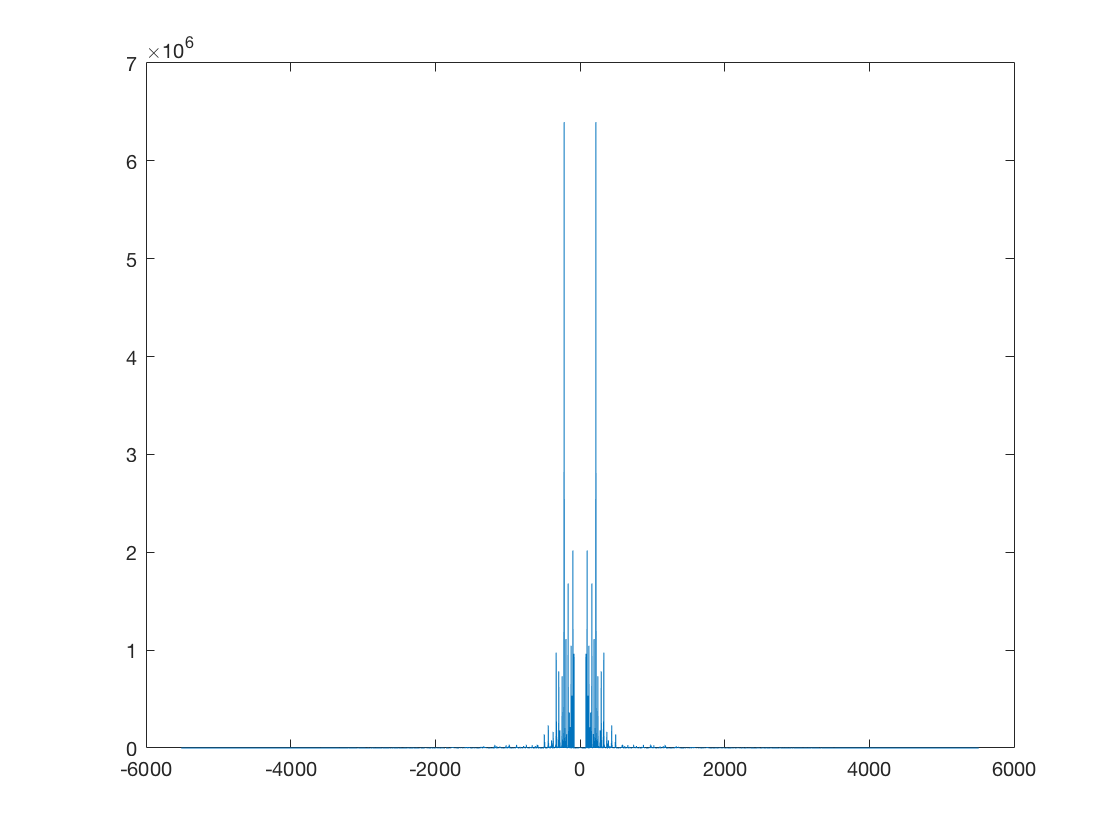

d_f = Fs/length(data_);
f = (-B/2):d_f:(B/2-d_f);
F = abs(fft(data_, length(f))).^2;

figure(2)
plot(f, fftshift(F))

Valutazione del SNR rispetto a quello teorico

N=var(err);
S=var(data_);

reale = 10*log10(S/N)

reale = 28.4800


teorico_pdf_gaussiana = 10*log10((3*M^2)/(V^2)*S)

teorico_pdf_gaussiana = 28.7513


teorico_pdf_uniforme = 10*log10(M^2)

teorico_pdf_uniforme = 36.1236